# Worksheet 4, Part 3 / 4: Graph Modeling

*Author: *Zachary del Rosario, Fall 2022

*Important Note:* Worksheet 4 comes to you in **four parts**; `worksheet4_part1.mlx`, `worksheet4_part2.mlx`, `worksheet4_part3.mlx`, and `worksheet4_part4.mlx`

*Learning Objectives:* As a result of working through this notebook, you will learn:

- More about connecting modeling choices to answering a modeling question

- The fundamental concepts of graph theory: nodes, edges, different types of graphs, the adjacency matrix

- How to represent graphs in three different forms: as a picture, as a list of edges, and as an adjacency matrix

- How to interpret a graph in the context of a spreading infection

- How to build an adjacency matrix using Matlab tools

### Additional Files

Make sure to download these additional files from Canvas and place them in the same folder as this worksheet:

- `infected.csv`

- `simulate_absir.m`

clear;

## Modeling Questions

Last time, we considered the following modeling question:

- Will organizing society into pods ("podding") help slow the spread more than masking?

We decided that we **cannot** answer this question with the compartmental SIR model. We can see this fact very easily by looking at the equations that define the model


$$\Delta I_t = \beta \times I_t \times S_t \\
\Delta R_t = \gamma \times I_t \\
S_{t+1} = S_t - \Delta I_t \\
I_{t+1} = I_t + \Delta I_t - \Delta R_t \\
R_{t+1} = R_t + \Delta R_t$$


Note that there is just one parameter $\beta$ that determines the rate of infections in the model. In order for us to represent the effects of organizing into pods and wearings masks, we would need to modify a parameter in the model. Both interventions (masking and podding) would affect $\beta$; whichever intervention affects $\beta$ more will be the more effective intervention.

Essentially, with this compartmental SIR model, we have to assume the answer to our question—the relative strength of masking or podding as expressed by changes to $\beta$—in order to implement the model. The compartmental model contributes nothing to answering this question.

However, masking and podding have *very* different implementations. If we switch to an agent-based model, we can represent these differences within our model: We could modify the social connections between individuals to represent podding and use the infectivity rate to represent masking. We could even make quantitative comparisons, such as testing a variety of pod sizes to help make policy decisions.

This is our first example of justified complexity: Since our model is not able to answer our modeling question, it would be reasonable to make our model more complex in a *deliberate* way.

### **Exercise 1 / 12**

For each of the modeling questions noted below, explain how how you could use an agent-based model to answer that question. Since this builds on questions you already saw in Worksheet 4 Part 1, try to get more detailed with your answers.

- What changes should I make to my behavior to avoid getting infected?

- *    (Write your answer here) *Track individuals who wear masks, practice social distancing, etc., and see who is the least likely to get infected, or if there is even a change in the likelihood of getting infected at all.

- Do international travel bans work to prevent the spread of disease *after* cases have been identified from international travel?

- *    (Write your answer here) *Check if individuals have traveled internationally and then implement bans and see if that affects the rate of infection.

Agent-based models could help us answer a variety of new modeling questions! However, these models are *far* more complex than the simple comparmental models we've studied so far. In order to handle this new class of models, we'll need to learn some new mathematical ideas: *graph theory*.

## Graph Theory Fundamentals

Let's learn about graphs!

### Graph Definition

A [graph](https://en.wikipedia.org/wiki/Graph_(discrete_mathematics)) is a mathematical object defined by two components: *nodes* and *edges*. Nodes are discrete points, while edges are connections between two nodes.

In this worksheet we'll (eventually) use nodes to represent individual people and edges to represent social connections between persons. But before we talk about specific populations, let's first get a handle on what graphs are like.

The following is an example of a graph with 6 nodes and 7 edges. Note that every edge is associated with two nodes.

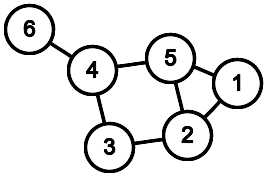

Since a graph is defined in terms of its nodes and edges, we can *construct* a graph simply by defining its edge data.* (So long as every node is connected by at least one edge!)

The following code shows how we could construct the graph pictured above.

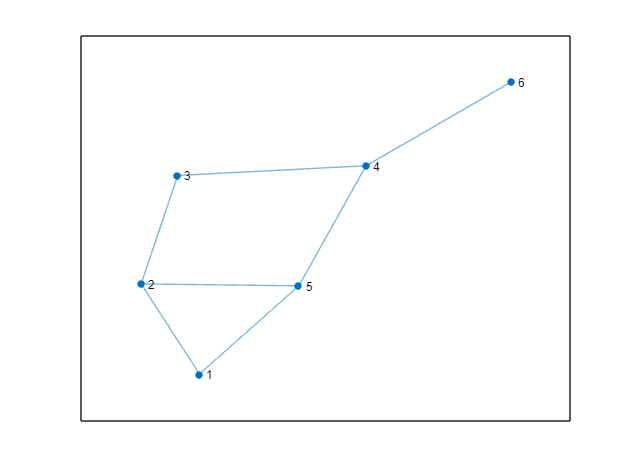

% Define the edge data
Edge_simple_start = [1 2 3 4 5 5 6];
Edge_simple_end   = [2 3 4 5 1 2 4];

% Construct the graph
Graph_simple = graph(Edge_simple_start, Edge_simple_end);

% Visualize
figure()
plot(Graph_simple)

Note that the nodes are not in the same location as the picture above! That is because a graph is defined in terms of its nodes and edges, and nothing else. The spatial layout of the nodes & edges is completely arbitrary. (*Technical note*: When we call `plot(G)` on a graph `G`, Matlab uses a [graph layout algorithm](https://en.wikipedia.org/wiki/Graph_drawing) to visualize the graph. This is a cool area of graph theory that we won't talk much about!)

The `graph` object in Matlab is a very useful implementation of a graph. For instance, we can print the graph to get some key information about the graph:

% Show the simple graph's properties
Graph_simple

Graph_simple =   graph with properties:

    Edges: [7×1 table]
    Nodes: [6×0 table]


This graph has 6 nodes and 7 edges. We *could* count up all of these elements from the plot, but it's far easier to just print the graph summary.

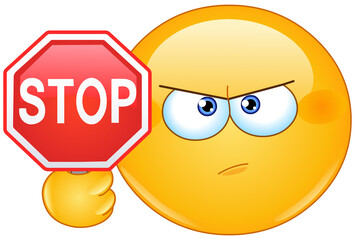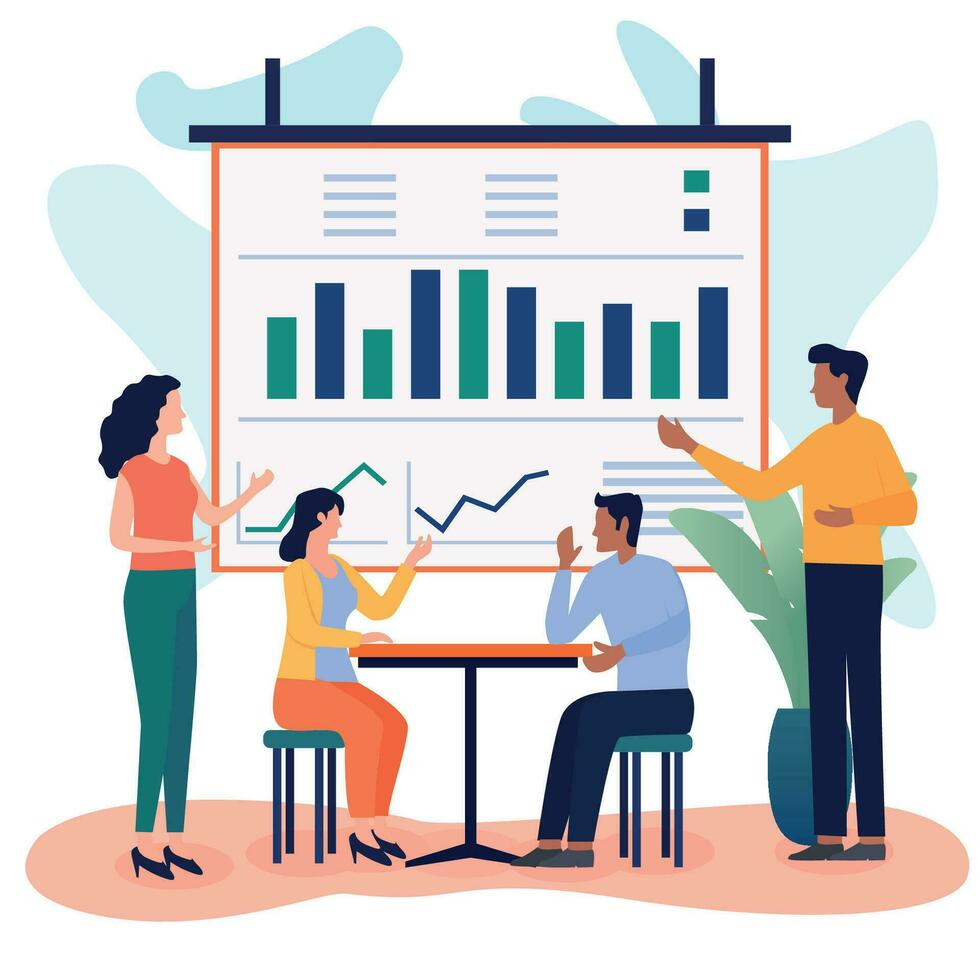

### Exercise 2 / 12

**STOP AND DISCUSS **this reading with your table. Try teaching it to a table mate, and see if you have the same understanding!

What were some things that you both understood, and were there any things you were both confused by?

(Capture any notes from your discussion here) We both understood that the number of times each number showed up in edge_simple_start and edge_simple_end was dependent on how many edges it was connected to

### Exercise 3 / 12

Construct the following graph and visualize it. Answer the questions below.

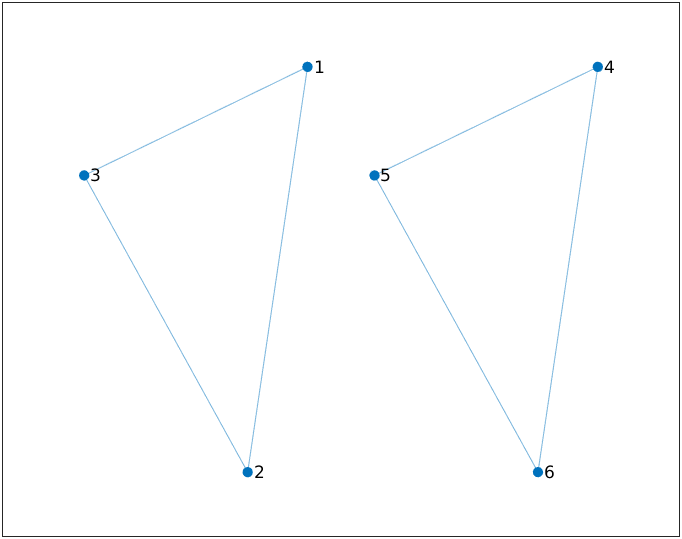

% TODO: Define the edge data
edgestart = [1 2 3 4 5 6]

edgestart =      1     2     3     4     5     6


edgeend = [2 3 1 5 6 4]

edgeend =      2     3     1     5     6     4


% TODO: Construct the graph
Graph_disconnected = graph(edgestart, edgeend)

Graph_disconnected =   graph with properties:

    Edges: [6×1 table]
    Nodes: [6×0 table]


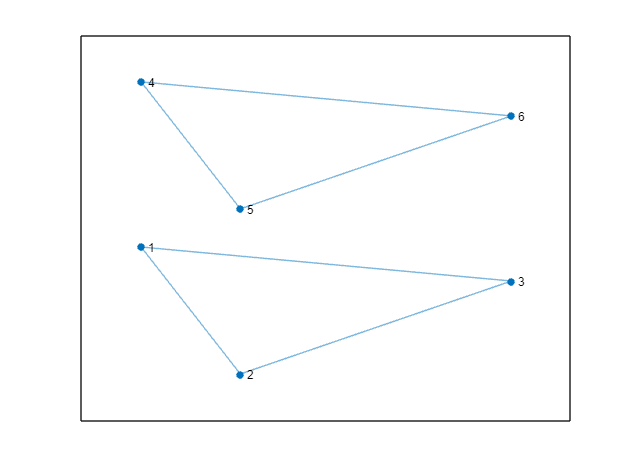

figure()
plot(Graph_disconnected)

- Is there any pathway (continuous set of edges) connecting Node 1 and Node 6?

- *    (Write your answer here) *No

- Imagine that every node represents a person, and that an infection can only spread across edges. Suppose that Person 1 is infected with a disease. Will the disease spread across the entire population?

-  *(Write your answer here) *No, because person 1, 2, and 3 are only in contact with each other.

### Example Graphs

Let's look at some example graphs to get a sense of graph properties.

A *dense* graph is a graph with lots of edges. For instance, the following graph has six nodes like the previous one, but it has more edges:

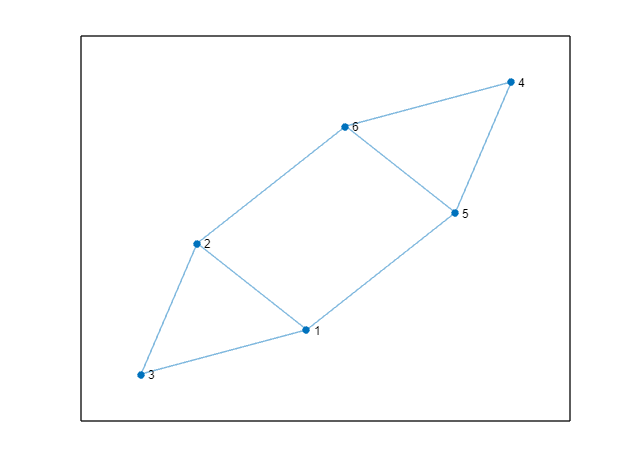

% Define a dense graph
Edge_dense_start = [1 2 3 4 5 6 1 2];
Edge_dense_end   = [2 3 1 5 6 4 5 6];
Graph_dense = graph(Edge_dense_start, Edge_dense_end);
figure()
plot(Graph_dense)

The graph above is also called a *connected* graph; there is a pathway (across edges) between every pair of nodes in the graph. Put differently, there exists some way to "get" from one node to any other node. If an infection started with a single person in this graph, it is possible (but not guaranteed!) for the infection to spread across the entire population.

The most edges we could have is where *every* node is connected to *every other* node; this is called a *complete* graph.

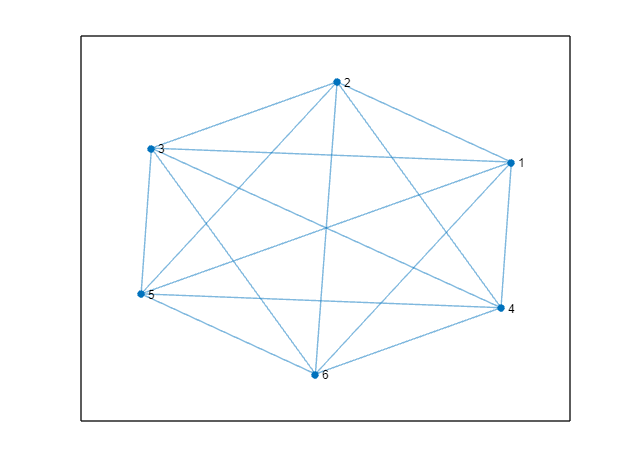

% Define a complete graph
% NOTE: The careful reader might recognize this matrix from the previous
% part of the worksheet. We'll talk about the connection to matrices soon!
Graph_complete = graph(ones(6, 6) - eye(6)); 
figure()
plot(Graph_complete)

Graph_complete

Graph_complete =   graph with properties:

    Edges: [15×2 table]
    Nodes: [6×0 table]


This complete graph allows for *maximal* spread of an infection; since every person is connected to every other person, the infection has many pathways to follow.

Conversely, a *sparse* graph is a graph with relatively few edges.

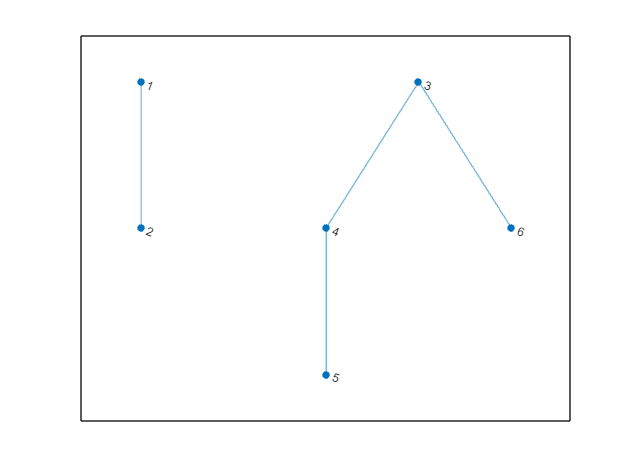

% Define a sparse graph
Edge_sparse_start = [1 3 4 3];
Edge_sparse_end   = [2 4 5 6];
Graph_sparse = graph(Edge_sparse_start, Edge_sparse_end);
figure()
plot(Graph_sparse)

The graph above is also another example of a *disconnected* graph. A *disconnected* graph is simply a graph that is not connected; there is at least one pair of nodes that are not connected by a pathway of edges.

These are all very simple graphs. However, much more complex graphs arise in the real world. Let's look at a graph from some real-life social network data to see what real graphs are like.

### Exercise 4 / 12

**STOP AND DISCUSS: **With your table, draw a new example of each type of graph on the whiteboard! What kind of graph did you draw?

(Insert a picture of your table's work here)

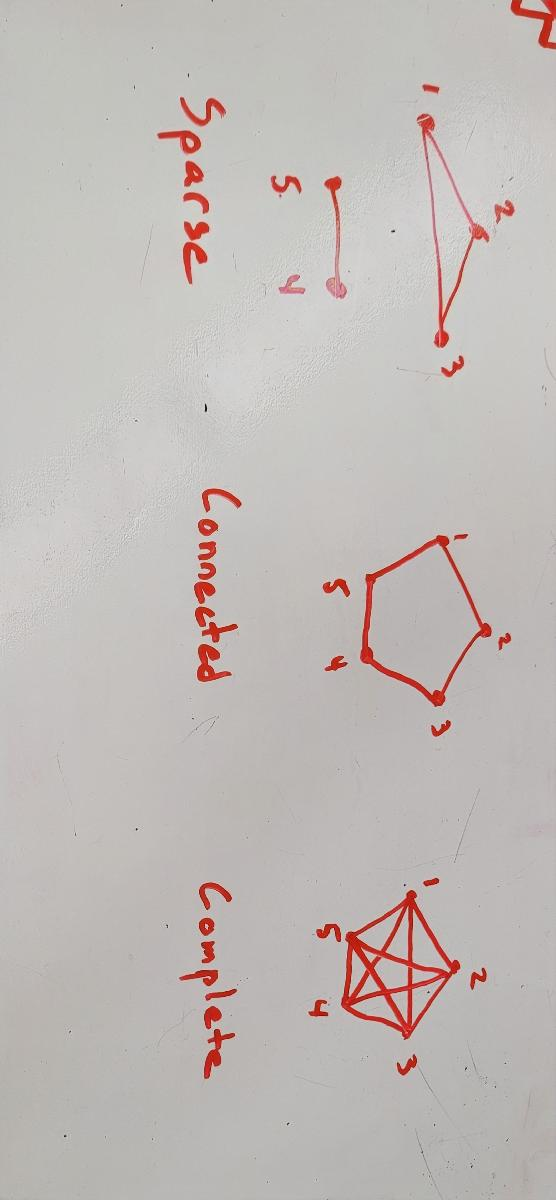

### Exercise 5 / 12

In this exercise, you'll investigate the connections between all of the "friends" of a single facebook user. You'll load some graph data where every node represents one person, and every edge represents a "friendship."

Follow these instructions:

- Download the file `facebook.tar.gz` from the [SNAP website](https://snap.stanford.edu/data/ego-Facebook.html).

- Extract the files; move the file `0.edges` to the same folder as this worksheet. (Make sure you `Change current folder...` to the worksheet folder!) *Important note:* If you're on Windows, you'll need software to unzip `tar.gz` files. I recommend [7zip](https://www.7-zip.org/), which is free and open-source.

- Run the code and answer the questions below.

*Hint*: The definitions in the questions below are mentioned above. The [Wikipedia article on graphs](https://en.wikipedia.org/wiki/Graph_(discrete_mathematics)#Types_of_graphs) also contains these definitions.

*Note*: I use some more advanced [graph layout features](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.graphplot.layout.html#mw_64bc3199-3569-46f6-bac8-04aea925933a) to help visualize this dataset effectively.

% TODO: Once you've downloaded the `0.edges` file and relocated it,
% write some code to determine the size of the graph
% NOTE: Matlab might complain about `textread()` and suggest `textscan()`
% instead. Ignore this suggestion.
Array_edges = textread('0.edges', '');

% I use some graph theory tricks to de-duplicate the two-way edges
% https://www.mathworks.com/matlabcentral/answers/308924-removing-duplicate-edges
d = digraph(Array_edges(:, 1), Array_edges(:, 2));
m = full(adjacency(d));
Graph_fb0 = graph(m|m', d.Nodes);

% TODO: Determine the graph's size
Graph_fb0

Graph_fb0 =   graph with properties:

    Edges: [2519×1 table]
    Nodes: [347×0 table]


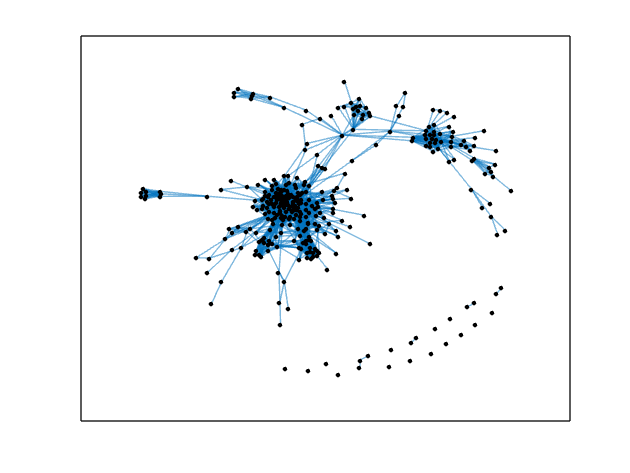

% The following code will visualize the social network graph

figure()
% NOTE: The following code uses some graph vis tricks
% I'm not expecting you to know how to do this!
h = plot(Graph_fb0, 'NodeColor', 'k', 'LineWidth', 0.1);
layout(h, 'force', 'UseGravity', true)

- How many nodes does this graph have? How many edges? (Don't count them by hand!!!)

-  *(Write your response here) *It has 2519 edges and 347 nodes.

- Is this a *complete *graph? How do you know?

-  *(Write your response here) *No, because you can see that not every node is connected to every other node.

- Is this a *connected* graph? How do you know?

-  *(Write your response here) *No, because you can see nodes that are connected to only one other node or no other nodes.

- How dense is this graph? Are there portions of the graph that are more dense than others?

-  *(Write your response here) *Yes, the middle is much more dense than the corner.

- Now imagine that a single person in this graph got sick (or had a *sick *idea for a meme!). How would the infection spread if that person were in one of the more dense regions of the graph? How would the infection spread if that person were in one of the more sparse regions?

-  *(Write your response here) *The infection would spread much faster if the person was in a more dense region or much slower if they were in one of the more sparse regions

- Open the edge data file `0.edges` with a text editor (Notepad will work just fine!). Compare the file against the data loaded into the `Array_edges` variable. How is the edge data represented in the file `0.edges`? 

-  *(Write your response here) *They're both stored in a 5038 x 2 array.

### Edge Weights

So far we have thought of edges as *binary* objects: either present or absent. In reality connections between people are highly variable. There are some people in your life that you interact with every day, while others you only see once a year. One way to represent differences across connections is to define a numerical *weight* associated with edge. These numerical values are called *edge weights*.

For instance, the following is a dense graph with unequal edge weights.

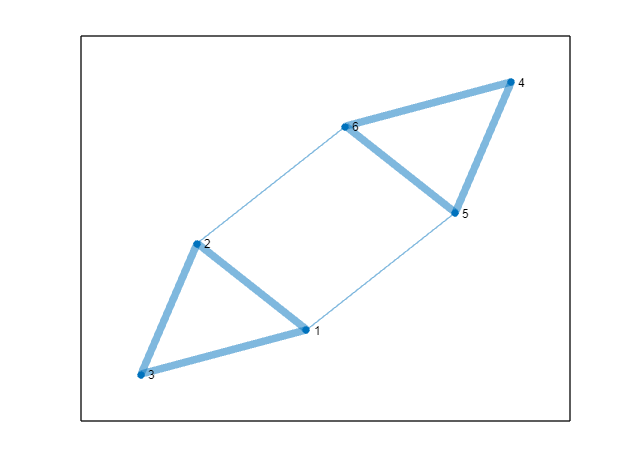

% Define a dense, weighted graph
Edge_dense_start = [1 2 3 4 5 6 1 2];
Edge_dense_end   = [2 3 1 5 6 4 5 6];
Weight_dense     = [9 9 9 9 9 9 1 1]; % Define weights for each edge
Graph_weighted = graph(Edge_dense_start, Edge_dense_end, Weight_dense);
figure()

% Visualize the edge weights
LWidths = 5 * Graph_weighted.Edges.Weight / max(Graph_weighted.Edges.Weight);
plot(Graph_weighted, 'LineWidth', LWidths)

Nodes 1, 2, 3 are all strongly connected to each other, as are Nodes 4, 5, 6. However, the connections between 1-to-5 and 2-to-6 are relatively weak.

Weights can be used to represent all sorts of properties: If the nodes represent cities, the weights might represent the distance between each city. If the nodes are websites, then the weights might represent the number of links between each website. In our case we'll use nodes to represent people, and the weights to represent the relative ease with which something (a disease, a meme, etc.) can spread between two people.

### Exercise 6 / 12

Use edge weights to model a "podding" situation where there are two pods of two people. The edges within the pod should be strong, while the connections across pods should be weak. Answer the questions below.

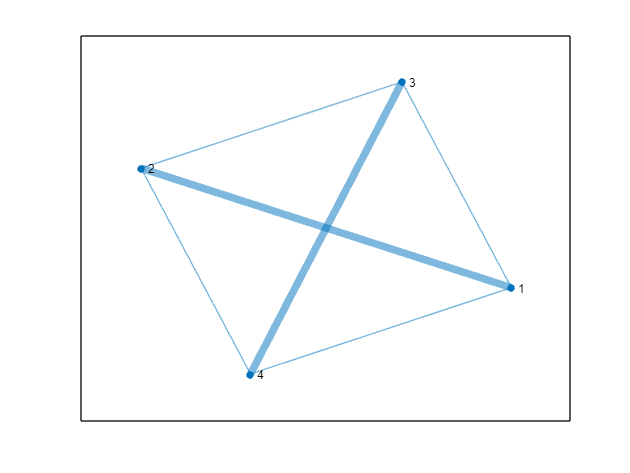

% Study a graph with 4 nodes
Edge_pod_start = [1 2 3 4 1 2];
Edge_pod_end   = [2 3 4 1 3 4];

% TODO: Define weights to model two "pods" of two people
Weight_pod = [9 1 9 1 1 1]; % EDIT THIS

% NOTE: No need to edit this
Graph_pod = graph(Edge_pod_start, Edge_pod_end, Weight_pod);
figure()
LWidths = 5 * Graph_pod.Edges.Weight / max(Graph_pod.Edges.Weight);
plot(Graph_pod, 'LineWidth', LWidths)

- Is this a complete graph?

-  *(Write your answer here) *Yes

- Would an infection spread *evenly* across this population?

-  *(Write your answer here) *No, because the population does not interact with everyone equally.

- This graph has 4 nodes and 6 edges. Imagine we had a complete graph with 5 nodes; how many edges would that have?

-  *(Write your answer here)* 10 edges

- Now imagine you wanted to model a "podding" situation with 5 people. How *painful* would writing down the edge & weight data be for this graph?

-  *(Write your answer here)* It would be less painful because there is a small number of people.

- Now imagine you wanted to model a "podding" situation with 100 people. *Approximately *how *painful* would writing down the edge & weight data be for this graph?

-  *(Write your answer here) *Very painful because it's a large number.

### Graphs and Matrices: The Adjacency Matrix

Hopefully the previous exercise highlighted a very important fact: Large populations have a lot of edges! Manually specifying the edge weight data for even 100 people would be *extremely painful*. Luckily there are more convenient ways to specify the edge weight data for a graph. We can use an *adjacency matrix* to represent the graph.

The `adjacency()` function will obtain the adjacency matrix from a graph object:

% Obtain the adjacency matrix for the simple graph
adjacency(Graph_simple)

ans =    (2,1)        1
   (5,1)        1
   (1,2)        1
   (3,2)        1
   (5,2)        1
   (2,3)        1
   (4,3)        1
   (3,4)        1
   (5,4)        1
   (6,4)        1
   (1,5)        1
   (2,5)        1
   (4,5)        1
   (4,6)        1


This doesn't look like a matrix!!! That's because Matlab stores the adjacency matrix in *sparse* form: a list of matrix entries and values. All values that are not listed are presumed to be zero.

We can use the `full()` command to get the "usual" form of the matrix:

% Obtain the full adjacency matrix for the simple graph
M_simple = full(adjacency(Graph_simple))

M_simple =      0     1     0     0     1     0
     1     0     1     0     1     0
     0     1     0     1     0     0
     0     0     1     0     1     1
     1     1     0     1     0     0
     0     0     0     1     0     0


% Plot the simple graph for comparison
figure(); plot(Graph_simple)

Every entry of the adjacency matrix represents a (potential) edge in the graph: The location along the rows corresponds to a node on one end of the edge, and the location along the columns corresponds to the node on the other end. 

For instance, Row 3, Column 5 of the adjacency matrix corresponds to the edge between Node 3 and Node 5. Since the simple graph has no edge between these two nodes, the adjacency matrix for the simple graph has a `0` in Row 3, Column 5. Meanwhile, Row 5, Column 4 has a `1` because Nodes 5 and 4 are connected.

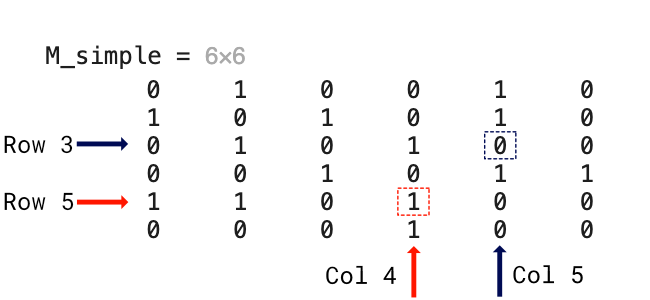

Note that in the graphs we've seen so far, if Node A is connected to Node B (say, 1 to 2), then Node B is connected to Node A (say, 2 to 1). Put differently, the edges are *undirected*. Consequently, the adjacency matrix is *symmetric* $M = M^{\top}$, which also implies that $M - M^{\top} = 0$ (the zero matrix, not the scalar zero!). We can check this easily using a line of Matlab code:

% Check symmetry of the adjacency matrix
M_simple - M_simple'

ans =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


The adjacency matrix for a *weighted* graph is similar, except that the values are no longer just `1`'s, but rather the weights of the edges. You'll learn how to extract the weighted adjacency matrix from a graph in the next exercise.

### Exercise 7 / 12

Obtain the weighted adjacency matrix from `Graph_weighted`.

*Hint*: Consult the documentation for the `adjacency()` function to learn how to get the weighted adjacency matrix.

% TODO: Obtain the adjacency matrix from the weighted graph
M_weighted = adjacency(Graph_weighted, 'weighted')

M_weighted =    (2,1)        9
   (3,1)        9
   (5,1)        1
   (1,2)        9
   (3,2)        9
   (6,2)        1
   (1,3)        9
   (2,3)        9
   (5,4)        9
   (6,4)        9
   (1,5)        1
   (4,5)        9
   (6,5)        9
   (2,6)        1
   (4,6)        9
   (5,6)        9



% NOTE: Don't edit this; use this to check your work
assert(max(M_weighted, [], 'all') > 1)
disp('Assertions passed!')

Assertions passed!



% Visualize the graph for comparison
figure()
LWidths = 5 * Graph_weighted.Edges.Weight / max(Graph_weighted.Edges.Weight);
plot(Graph_weighted, 'LineWidth', LWidths)

We can extract the adjacency matrix from an existing graph, but we can also go the other direction: We can *build *a graph from an adjacency matrix.

### Constructing graphs with matrices

Remember from the previous part of Worksheet 4 when we considered an infection vector that depended on specific persons?


$$v_{1, \text{infect}} = I_2 + I_4 \\
v_{2, \text{infect}} = I_1 \\
v_{3, \text{infect}} = 0 \\
v_{4, \text{infect}} = I_1$$


We turned this set of equations into a matrix equation $\vec{v}_{\text{infect}} = M \vec{I}$, where $M$ is given by

% Convert the equations above into matrix form
M_specific = [
    0  1  0  1;
    1  0  0  0;
    0  0  0  0;
    1  0  0  0
]

M_specific =      0     1     0     1
     1     0     0     0
     0     0     0     0
     1     0     0     0


It turns out this is an adjacency matrix! (Surprise!) We can construct a graph from the adjacency matrix using `graph()`.

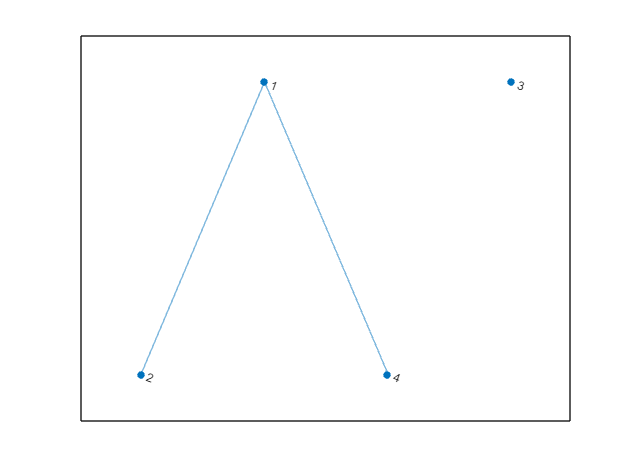

% Construct a graph from the adjacency matrix
Graph_specific = graph(M_specific);
figure(); plot(Graph_specific)

This means there is a tight connection between the sets of equations we discussed last time and the graphs we're discussing now. We can use the same matrix construction techniques from the previous part of the worksheet to build graphs.

### Exercise 8 / 12

Construct an adjacency matrix for a complete graph with the number of nodes specified in `n_population`. Answer the questions below.

*Hint*: We learned how to do this in Part 2 of Worksheet 4.

% Consider a population of 100 persons
n_population = 100;

% TODO: Construct the adjacency matrix
M_100 = ~eye(n_population, n_population); % Fix this

% NOTE: Do not edit these lines; 
% use this to check your work
assert(all(diag(M_100) == 0), 'The diagonal of M should be zeros')
assert(sum(M_100, 'all') == 1e4 - 100, 'The matrix M should have 9900 nonzero entries')
disp('Assertions passed!')

Assertions passed!


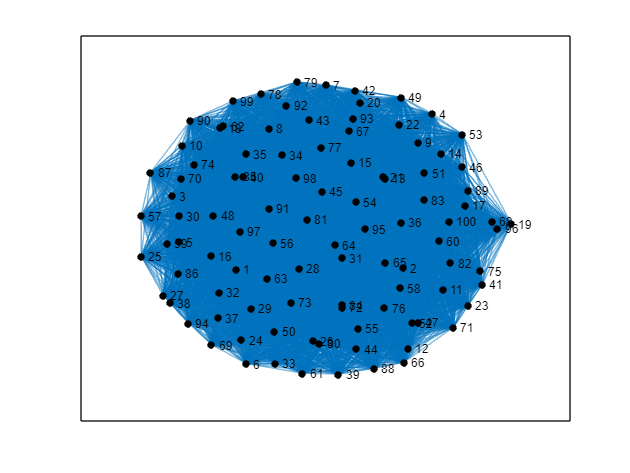


% Visualize the graph
Graph_100 = graph(M_100);
figure()
plot(Graph_100, 'NodeColor', 'k')

**STOP AND DISCUSS:** For each of the scenarios below, discuss with your **table** whether this (unweighted) complete graph be a good model for this scenario. Why or why not?

- Imagine this graph is meant to represent a small company with 100 employees spread across 5 departments. Employees mostly interact (face-to-face) with people in their own department, and only occasionally interact with people from other departments. Would this (unweighted) complete graph be a good model for this scenario? Why or why not?

-  *(Your ****table's**** answer here)*

No, a weighted graph would be a better model because employees interact with their own departement more than other departments.

- Now imagine this graph is meant to represent the 100 students at a small engineering college where "everyone knows everyone." All students take the same classes and live in the same dorm. Would this (unweighted) complete graph be a good model for this scenario? Why or why not?

-  *(Your ****table's**** answer here) *Yes, because everyone interacts with everyone.

## Modeling Social Situations

Now that we've learned how to interpret and build graphs, let's put that knowledge to use in order to model some social situations!

### Modeling Pods

Let's imagine organizing society into "pods." There are various approaches we could take to modeling the connections between individuals in a "podding" scenario—we'll look at multiple and compare them to get a sense for how to model social situations.

We will start (deliberately!) with very small numbers of people to focus on the *types *of graphs we might use before we scale things up to a large number of people. We'll see in the next section that we'll need to learn *even more* Matlab tricks to build the adjacency matrices necessary for these (justifiably!) complex models.

Suppose we model pods with the following graph (represented by an adjacency matrix). Let's call this the "airtight" pod graph (for reasons that will be apparent soon):

% "Airtight" pod
M_airtight = [
    0 1 1 0 0 0;
    1 0 1 0 0 0;
    1 1 0 0 0 0;
    0 0 0 0 1 1;
    0 0 0 1 0 1;
    0 0 0 1 1 0
];

Graph_airtight = graph(M_airtight);
figure(); plot(Graph_airtight)

You'll think critically about this graph in the next exercise.

### Exercise 9 / 12

Answer the following questions using the "airtight" pod graph shown immediately above.

- Suppose that "podding" society means organizing every individual into small groups and *limiting* their contact with the people outsider their "pod." Would the "airtight" pod be a good model for this scenario?

-  *(Write your response here) *No, because limited contact doesn't mean no contact.

- Suppose that "podding" society means organizing every individual into small groups and *totally preventing* their contact with the people outsider their "pod." Would the "airtight" pod be a good model for this scenario?

-  *(Write your response here) *Yes, because no one ever interacts with anyone else.

Let's consider an alternative graph where the pods are "leaky"—there are weak but nonzero edges across pods.

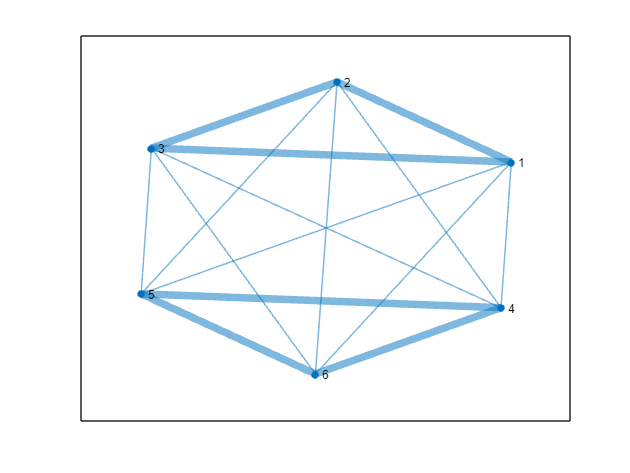

% "Leaky" pod
M_leaky = [
    0 5 5 1 1 1;
    5 0 5 1 1 1;
    5 5 0 1 1 1;
    1 1 1 0 5 5;
    1 1 1 5 0 5;
    1 1 1 5 5 0;
];
Graph_leaky = graph(M_leaky);

figure()
LWidths = 5 * Graph_leaky.Edges.Weight / max(Graph_leaky.Edges.Weight);
plot(Graph_leaky, 'LineWidth', LWidths)

### Exercise 10 / 12

Use the "leaky pod" graph immediately above to answer the following questions.

- Compare the "leaky" pod graph with the "airtight" pod graph from earlier. In your own words, state the differences between these two graphs.

-  *(Write your answer here) *In the airtight pod graph, no one ever interacts with anyone else. In the leaky pod graph, those in the pod interact with people outside the pod, though they interact with the pod much more than those outside of it.

- Suppose that "podding" society means organizing every individual into small groups and *limiting* their contact with the people outsider their "pod." Would the "leaky" pod be a good model for this scenario?

-  *(Write your answer here) *Yes, because individuals still interact with others outside their pod, but not as much as those in their pod.

### Assembling the pods

Regardless of what kind of "podding" model we want to implement, we'll have issues if we try to write out the adjacency matrices for the graph by hand for a large number of people. The number of entries in a square matrix is $n^2$, so if we have 100 people in our model, we would need to write out $10,000$ matrix entries *manually*. **Do not do this. Seriously.**

In order to work smarter-not-harder, let's notice some patterns in the "leaky" pod model:

M_leaky

M_leaky =      0     5     5     1     1     1
     5     0     5     1     1     1
     5     5     0     1     1     1
     1     1     1     0     5     5
     1     1     1     5     0     5
     1     1     1     5     5     0


Looking at this adjacency matrix, we can see that there's a lot of *structure *in this matrix. It looks like the 6x6 matrix `M_leaky` is built from simpler 3x3 matrices:

M_pod = 5 * (ones(3, 3) - eye(3))

M_pod =      0     5     5
     5     0     5
     5     5     0


M_off = ones(3, 3)

M_off =      1     1     1
     1     1     1
     1     1     1


What if we tried to put the big matrix together by *combining* the smaller matrices? Let's see if that works in Matlab:

[
    M_pod, M_off;
    M_off, M_pod;
]

ans =      0     5     5     1     1     1
     5     0     5     1     1     1
     5     5     0     1     1     1
     1     1     1     0     5     5
     1     1     1     5     0     5
     1     1     1     5     5     0


**Wow!** This actually works! It turns out that Matlab has a large number of features for [expanding and concatenating matrices](https://www.mathworks.com/help/matlab/math/creating-and-concatenating-matrices.html). Using this, we can build large matrices from much smaller components. For instance, we could make a 9-person population with 3-person pods by expanding the matrix a bit:

[
    M_pod, M_off, M_off;
    M_off, M_pod, M_off;
    M_off, M_off, M_pod;
]

ans =      0     5     5     1     1     1     1     1     1
     5     0     5     1     1     1     1     1     1
     5     5     0     1     1     1     1     1     1
     1     1     1     0     5     5     1     1     1
     1     1     1     5     0     5     1     1     1
     1     1     1     5     5     0     1     1     1
     1     1     1     1     1     1     0     5     5
     1     1     1     1     1     1     5     0     5
     1     1     1     1     1     1     5     5     0


This is a useful trick to know! However, if we wanted to make a 100-person population, this would still be pretty labor-intensive. There are some additional matrix construction techniques we should learn to make this easier.

### Loop Assembly

An alternative approach to constructing an adjacency matrix is to *start* with a large matrix and make edits to it. For instance, we can start with a matrix of all zeros:

M_large = zeros(25, 25)

M_large =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0

And change one small section to represent an "airtight" pod:

M_pod5 = 5 * (ones(5, 5) - eye(5));
M_large(1:5, 1:5) = M_pod5

M_large =      0     5     5     5     5     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     5     0     5     5     5     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     5     5     0     5     5     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     5     5     5     0     5     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     5     5     5     5     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0

Note that the `(1:5)` syntax is called *slicing*; this allows us to access rectangular subsets of a matrix. Note that we can slice over both axes of a matrix: both its rows `r` and columns `c` with the syntax `M(r, c)`.

We could write multiple lines of code to edit these individual blocks. You'll practice slice assignment in the next exercise.

### Exercise 11 / 12

Modify the matrix `M_large` to model an "airtight" pod for individuals 6 through 10.

% TODO: Modify M_large 
M_large(6:10, 6:10) = M_pod5

M_large =      0     5     5     5     5     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     5     0     5     5     5     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     5     5     0     5     5     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     5     5     5     0     5     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     5     5     5     5     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     5     5     5     5     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     5     0     5     5     5     0     0     0     0

% NOTE: Do not edit this; use this to check your work
assert(min(M_large(6:10, 6:10) == M_pod5, [], 'all'))
disp('Assertions passed!')

Assertions passed!


For a 25-person population this would not be too much code, but it would still be inconvenient for a 100-person population.

Instead, we can use *loops *to automate the process of assigning the blocks. To do this, we'll need to do a bit of math to adjust the slicing code. For instance, this is how we could introduce 5-person "airtight" pods to the 25-person population:

for i = 1:5
    % Determine the slice indices
    slice_begin = (i - 1) * 5 + 1;
    slice_end = slice_begin + 5 - 1;
    % Apply the slice indices to modify the matrix
    M_large(slice_begin:slice_end, slice_begin:slice_end) = M_pod5;
end

M_large

M_large =      0     5     5     5     5     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     5     0     5     5     5     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     5     5     0     5     5     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     5     5     5     0     5     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     5     5     5     5     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     5     5     5     5     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     5     0     5     5     5     0     0     0     0

Honestly, figuring out slice indices is *really obnoxious*. However, once we figure out the correct indices for one case, we can pretty easily generalize it for larger and smaller pods.

The following code creates a 100-person "airtight" pod graph with pods of size 10.

% Build the adjacency matrix
M_100_airtight = zeros(100, 100);
M_pod10 = ones(10, 10) - eye(10);

for i = 1:10
    % Determine the slice indices
    slice_begin = (i - 1) * 10 + 1;
    slice_end = slice_begin + 10 - 1;
    % Apply the slice indices to modify the matrix
    M_100_airtight(slice_begin:slice_end, slice_begin:slice_end) = M_pod10
end

M_100_airtight =      0     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     0     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     0     1     1     1     1     1     1     0     0     0  

M_100_airtight =      0     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     0     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     0     1     1     1     1     1     1     0     0     0  

M_100_airtight =      0     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     0     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     0     1     1     1     1     1     1     0     0     0  

M_100_airtight =      0     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     0     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     0     1     1     1     1     1     1     0     0     0  

M_100_airtight =      0     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     0     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     0     1     1     1     1     1     1     0     0     0  

M_100_airtight =      0     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     0     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     0     1     1     1     1     1     1     0     0     0  

M_100_airtight =      0     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     0     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     0     1     1     1     1     1     1     0     0     0  

M_100_airtight =      0     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     0     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     0     1     1     1     1     1     1     0     0     0  

M_100_airtight =      0     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     0     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     0     1     1     1     1     1     1     0     0     0  

M_100_airtight =      0     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     0     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     0     1     1     1     1     1     1     0     0     0  

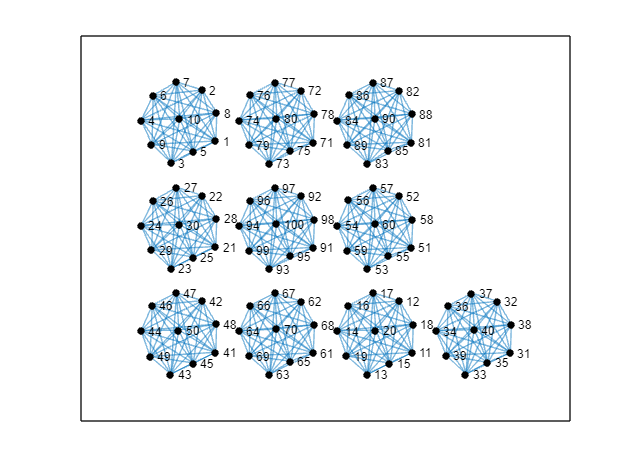


% Visualize the graph structure
Graph_100_airtight = graph(M_100_airtight);
figure(); 
h = plot(Graph_100_airtight, 'NodeColor', 'k', 'LineWidth', 0.1);
% NB. I use a graph layout algorithm that makes the distance between nodes
% inversely-proportional to the edge weight. This will tend to "clump" the
% pods together, which will make interpreting the graph visualization
% easier.
layout(h, 'force', 'WeightEffect', 'inverse')

You'll put these ideas to use to implement the "leaky" pod graph with a 100-person population.

### Exercise 12 / 12

Implement a 100-person "leaky" pod graph with 10 persons per pod. Choose your own strategy for implementing the adjacency matrix! Give connections within pods a weight of `10`, and connections across pods a weight of `1`.

% TODO: Create the adjacency matrix for the 100-person "leaky" pod model
M_off100 = ones(10,10)

M_off100 =      1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1


M_pod100 = 10 * (ones(10, 10) - eye(10))

M_pod100 =      0    10    10    10    10    10    10    10    10    10
    10     0    10    10    10    10    10    10    10    10
    10    10     0    10    10    10    10    10    10    10
    10    10    10     0    10    10    10    10    10    10
    10    10    10    10     0    10    10    10    10    10
    10    10    10    10    10     0    10    10    10    10
    10    10    10    10    10    10     0    10    10    10
    10    10    10    10    10    10    10     0    10    10
    10    10    10    10    10    10    10    10     0    10
    10    10    10    10    10    10    10    10    10     0



M_100 = [M_pod100, M_off100, M_off100, M_off100, M_off100, M_off100, M_off100, M_off100, M_off100, M_off100;
        M_off100, M_pod100, M_off100, M_off100, M_off100, M_off100, M_off100, M_off100, M_off100, M_off100;
        M_off100, M_off100, M_pod100, M_off100, M_off100, M_off100, M_off100, M_off100, M_off100, M_off100;
        M_off100, M_off100, M_off100, M_pod100, M_off100, M_off100, M_off100, M_off100, M_off100, M_off100;
        M_off100, M_off100, M_off100, M_off100, M_pod100, M_off100, M_off100, M_off100, M_off100, M_off100;
        M_off100, M_off100, M_off100, M_off100, M_off100, M_pod100, M_off100, M_off100, M_off100, M_off100;
        M_off100, M_off100, M_off100, M_off100, M_off100, M_off100, M_pod100, M_off100, M_off100, M_off100;
        M_off100, M_off100, M_off100, M_off100, M_off100, M_off100, M_off100, M_pod100, M_off100, M_off100;
        M_off100, M_off100, M_off100, M_off100, M_off100, M_off100, M_off100, M_off100, M_pod100, M_off100;
        M_off100, M_off100, M_off100, M_off100, M_off100, M_off100, M_off100, M_off100, M_off100, M_pod100;]

M_100 =      0    10    10    10    10    10    10    10    10    10     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
    10     0    10    10    10    10    10    10    10    10     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
    10    10     0    10    10    10    10    10    10    10     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
    10    10    10     0    10    10    10    10    10    10     1     1     1     1     

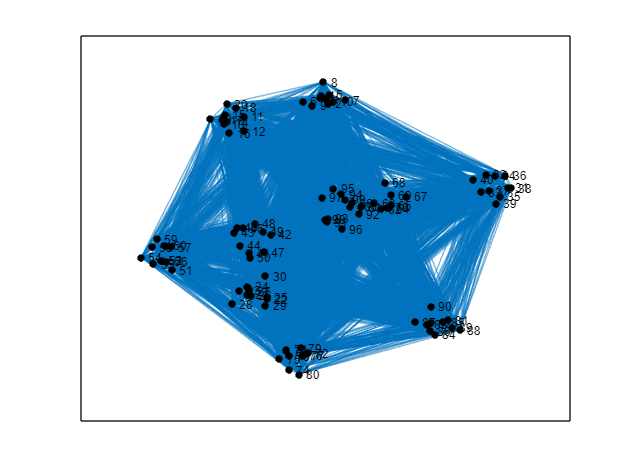

% Visualize the graph structure
Graph_100 = graph(M_100);
figure(); 
h = plot(Graph_100, 'NodeColor', 'k', 'LineWidth', 0.1);
% NB. I use a graph layout algorithm that makes the distance between nodes
% inversely-proportional to the edge weight. This will tend to "clump" the
% pods together, which will make interpreting the graph visualization
% easier.
layout(h, 'force', 'WeightEffect', 'inverse')


% NOTE: Do not edit this; use this to check your work
assert(abs(mean(M_100, 'all') - 1.8) < 1e-3)
disp('Assertions passed!')

Assertions passed!


Once you've got the graph implemented, we can run the agent-based SIR model on your graph!

% Define an initial infected state
v1 = zeros(n_total, 1);

Unrecognized function or variable 'n_total'.

v1(1) = 1;

% Run the model!
n_time = 150;
[Sh, Ih, Rh] = simulate_absir(M_100, v1, n_time, 0.1, 0.05);

A sparse matrix plot of the infection history `Ih` will show us the full history of infections across the population.

spy(Ih)

We can also summarize the full count of infected at each timestep.

Ihistory = sum(Ih, 1);

figure(); clf;
plot(Ihistory)

We can see that the total infection curve tends to be more "jagged" than it typically is. This is (likely!) because the disease can quickly spread through pods; once one person gets infected inside a pod, we're likely to see a large number of people (up to nine!) get infected soon thereafter.

## Looking Forward

We started off this worksheet by considering a modeling question comparing masking and podding. It took us a *lot* of work to set up the mathematical ideas to represent podding, but we're finally ready to do so! In the final part of Worksheet 4, we'll return to compare masking and podding, revisit the idea of *metrics*, and probe some of the assumptions underlying our models more deeply.